# Impact of waves on different lagrangian metrics

- Impact of aliasing

- Spectra and structure functions (both longitudinal and transverse)

- FSLE

clear all
close all 

%load('/Users/dhruvbalwada/Work/SWmodel/run_ag_0.4_aw_0.9_kmi_10/traj.mat');
%state = load('/Users/dhruvbalwada/Work/SWmodel/run_ag_0.4_aw_0.9_kmi_10/matlab.mat');
load('/Users/dhruvbalwada/Work/SWmodel/run_ag_0.4_aw_0.9_kmu20_kml13/traj.mat');
state = load(['/Users/dhruvbalwada/Work/SWmodel/run_ag_0.4_aw_0.9_kmu20_kml13/matlab.mat']);

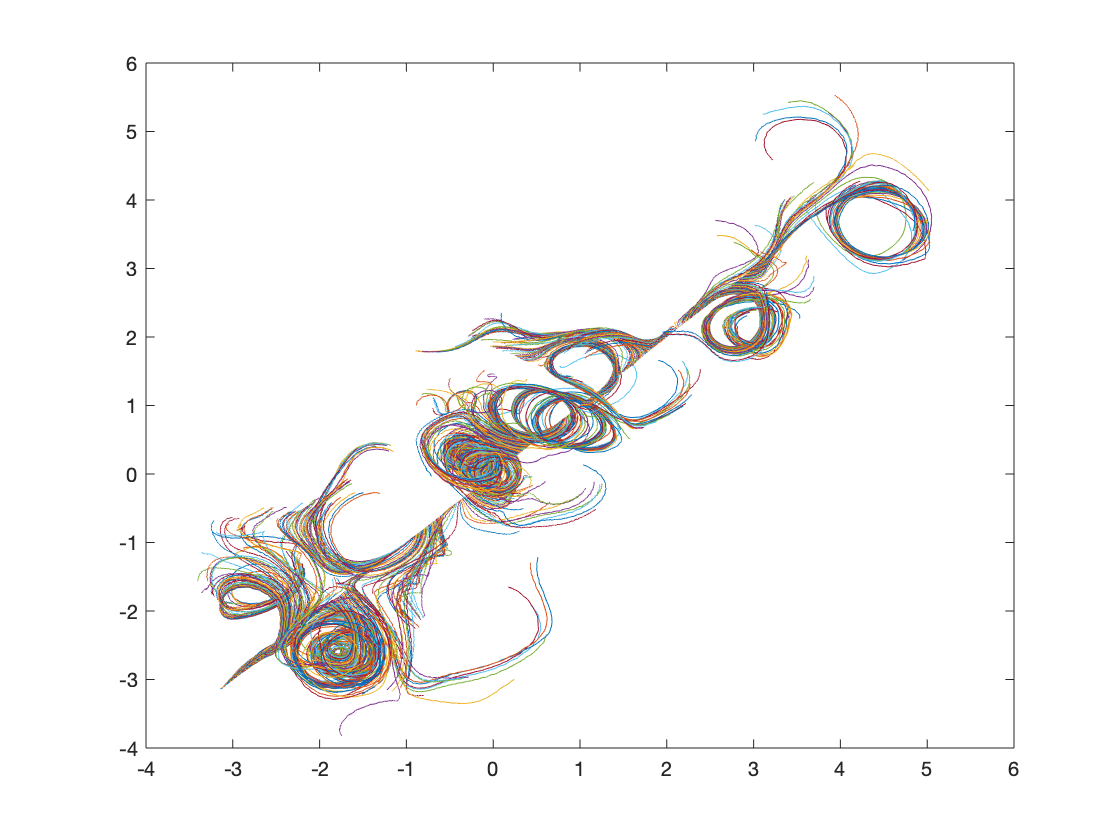

figure,
plot(trajX, trajY)

addpath /Users/dhruvbalwada/Work/SWmodel/rsw/
addpath /Users/dhruvbalwada/'Google Drive'/Main_projects/Relative_dispersion_acc/mesoscale_stirring_dimes_floats/codes/

Define a non-dim time tau = t*f

The period of an inertial oscillation is 2*pi in non-dim time.

traj_inertial_time = trajT*state.f;

Create aliased datasets

dT = mean(diff(traj_inertial_time)); % dT in inertial time
nres = ceil(2*pi/dT); % number of steps that make an inertial oscillation

traj_orig.T = traj_inertial_time; 
traj_orig.X = trajX;
traj_orig.Y = trajY;

traj_under_inertial_samp.T = traj_orig.T(1:ceil(nres*0.5):end);
traj_under_inertial_samp.X = traj_orig.X(1:ceil(nres*0.5):end,:);
traj_under_inertial_samp.Y = traj_orig.Y(1:ceil(nres*0.5):end,:);

traj_inertial_samp.T = traj_orig.T(1:nres:end);
traj_inertial_samp.X = traj_orig.X(1:nres:end,:);
traj_inertial_samp.Y = traj_orig.Y(1:nres:end,:);

traj_over_inertial_samp.T = traj_orig.T(1:ceil(nres*1.5):end);
traj_over_inertial_samp.X = traj_orig.X(1:ceil(nres*1.5):end,:);
traj_over_inertial_samp.Y = traj_orig.Y(1:ceil(nres*1.5):end,:);

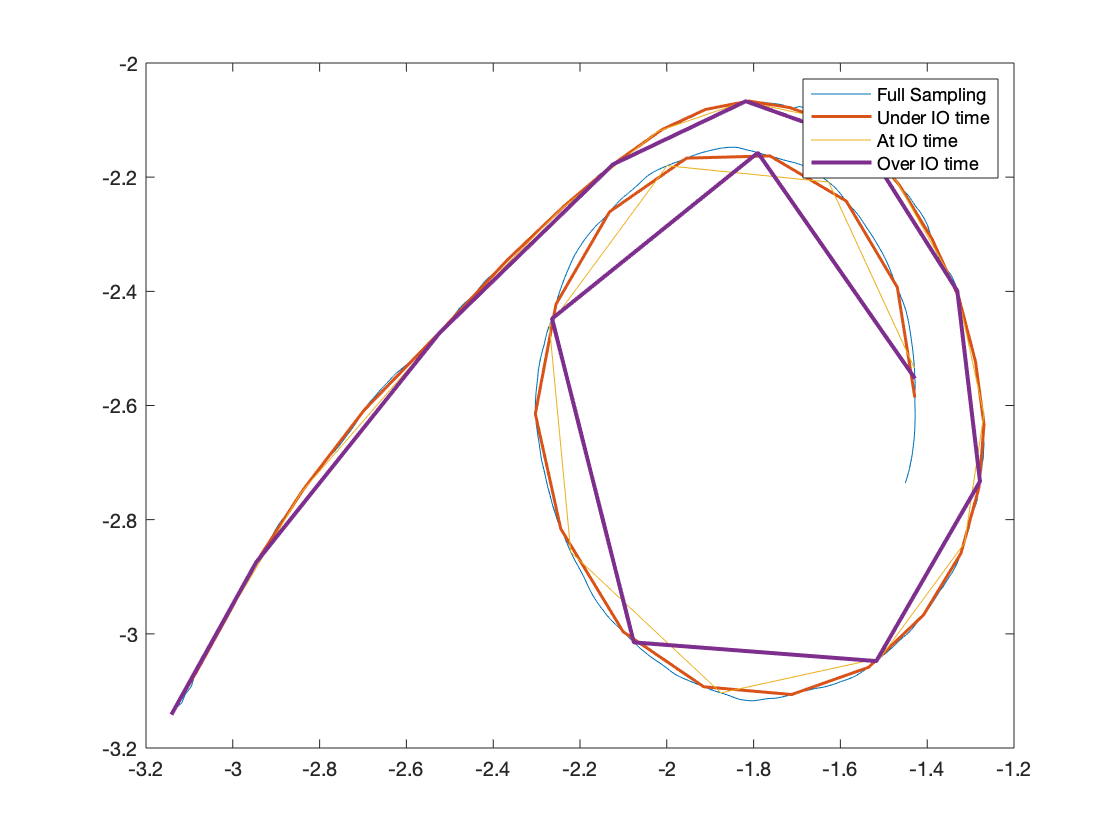

figure,
plot(traj_orig.X(:,1), traj_orig.Y(:,1))
hold all
plot(traj_under_inertial_samp.X(:,1), traj_under_inertial_samp.Y(:,1), 'linewidth',1.5)
plot(traj_inertial_samp.X(:,1), traj_inertial_samp.Y(:,1))
plot(traj_over_inertial_samp.X(:,1), traj_over_inertial_samp.Y(:,1), 'linewidth',2)
legend('Full Sampling','Under IO time','At IO time','Over IO time')

#### Lagrangian Frequency Spectra

traj_orig.CV = complex_vels(traj_orig);
traj_inertial_samp.CV = complex_vels(traj_inertial_samp);
traj_under_inertial_samp.CV = complex_vels(traj_under_inertial_samp);
traj_over_inertial_samp.CV = complex_vels(traj_over_inertial_samp);

traj_orig.U = [real(traj_orig.CV); zeros([1,512])]; 
traj_orig.V = [imag(traj_orig.CV); zeros([1,512])]; 
traj_inertial_samp.U = [real(traj_inertial_samp.CV); zeros([1,512])]; 
traj_inertial_samp.V = [imag(traj_inertial_samp.CV); zeros([1,512])]; 
traj_under_inertial_samp.U = [real(traj_under_inertial_samp.CV); zeros([1,512])];
traj_under_inertial_samp.V = [imag(traj_under_inertial_samp.CV); zeros([1,512])]; 
traj_over_inertial_samp.U = [real(traj_over_inertial_samp.CV); zeros([1,512])]; 
traj_over_inertial_samp.V = [imag(traj_over_inertial_samp.CV); zeros([1,512])]; 

traj_orig = spectra(traj_orig);

SLEPTAP calculating tapers of length 512.
SLEPTAP interpolating to length 2500.


traj_inertial_samp = spectra(traj_inertial_samp);

SLEPTAP calculating tapers of length 18.


traj_under_inertial_samp = spectra(traj_under_inertial_samp);

SLEPTAP calculating tapers of length 36.


traj_over_inertial_samp = spectra(traj_over_inertial_samp);

SLEPTAP calculating tapers of length 12.


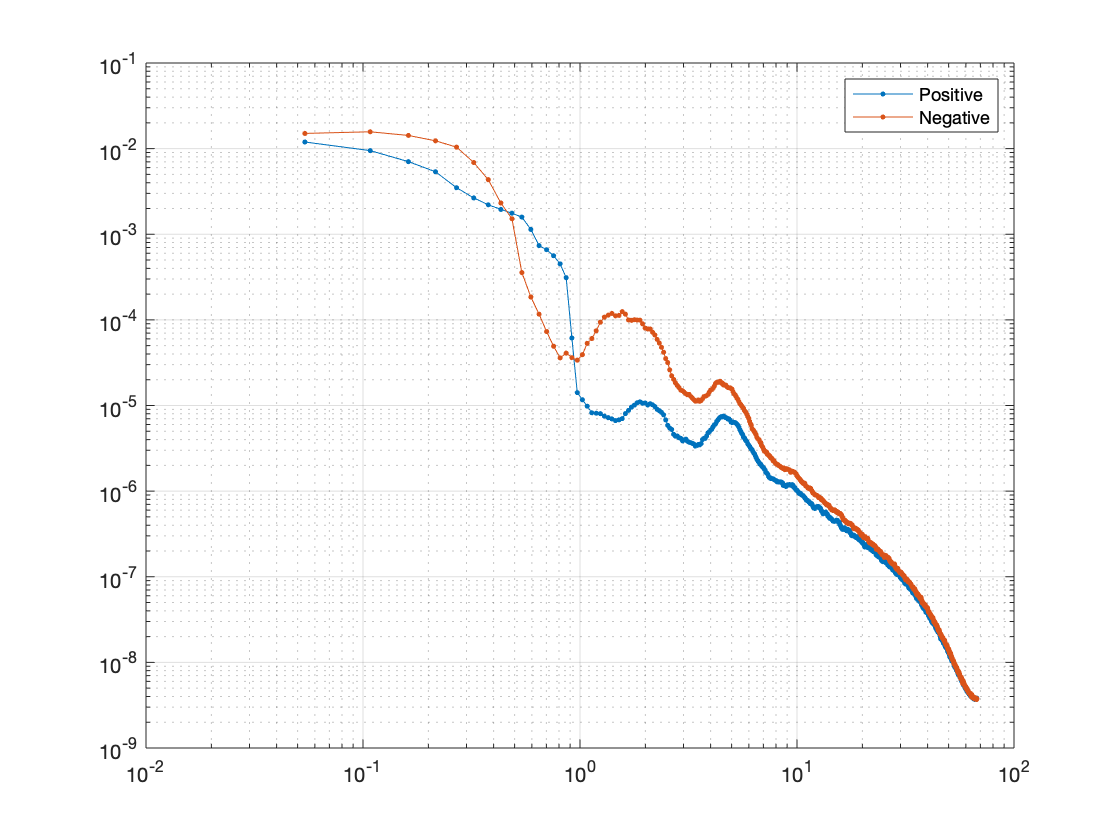

figure,
loglog(traj_orig.F*2*pi, nanmean(traj_orig.SPP,2),'.-')
hold all
loglog(traj_orig.F*2*pi, nanmean(traj_orig.SNN,2),'.-')
legend('Positive','Negative')
grid

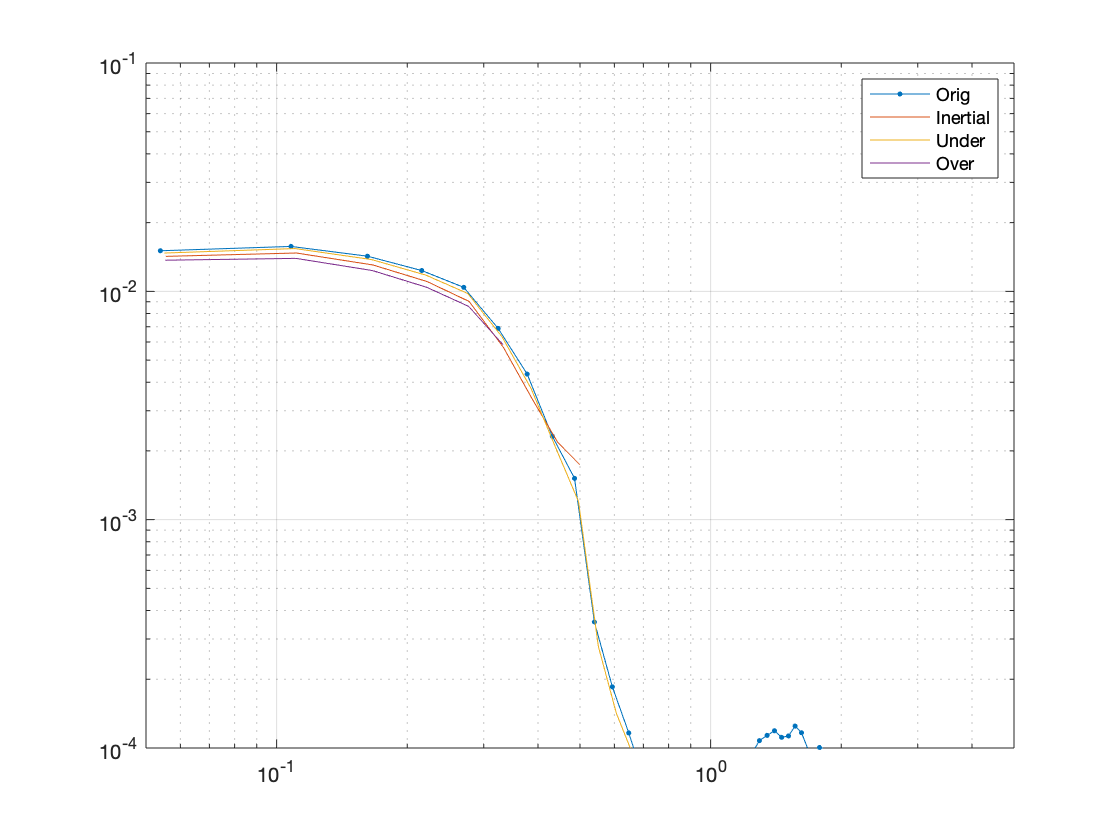

figure,
loglog(traj_orig.F*2*pi, nanmean(traj_orig.SNN,2),'.-')
hold all
loglog(traj_inertial_samp.F*2*pi, nanmean(traj_inertial_samp.SNN,2))
loglog(traj_under_inertial_samp.F*2*pi, nanmean(traj_under_inertial_samp.SNN,2))
loglog(traj_over_inertial_samp.F*2*pi, nanmean(traj_over_inertial_samp.SNN,2))

legend('Orig','Inertial','Under','Over')
axis([5e-2, 5, 1e-4, 1e-1])
grid

#### Structure functions and Spectra

Direct spectra and SFs from lagrangian obs, and 

% Wave-vortex spectra directly
[KEw,PEw,KEg,PEg,kes,pes,kesw,pesw,kesg,pesg] = wavevortdecomp(state.Sout,state.f,state.Cg);

%%
figure
loglog(kes,'linewidth',2)
hold

Current plot held


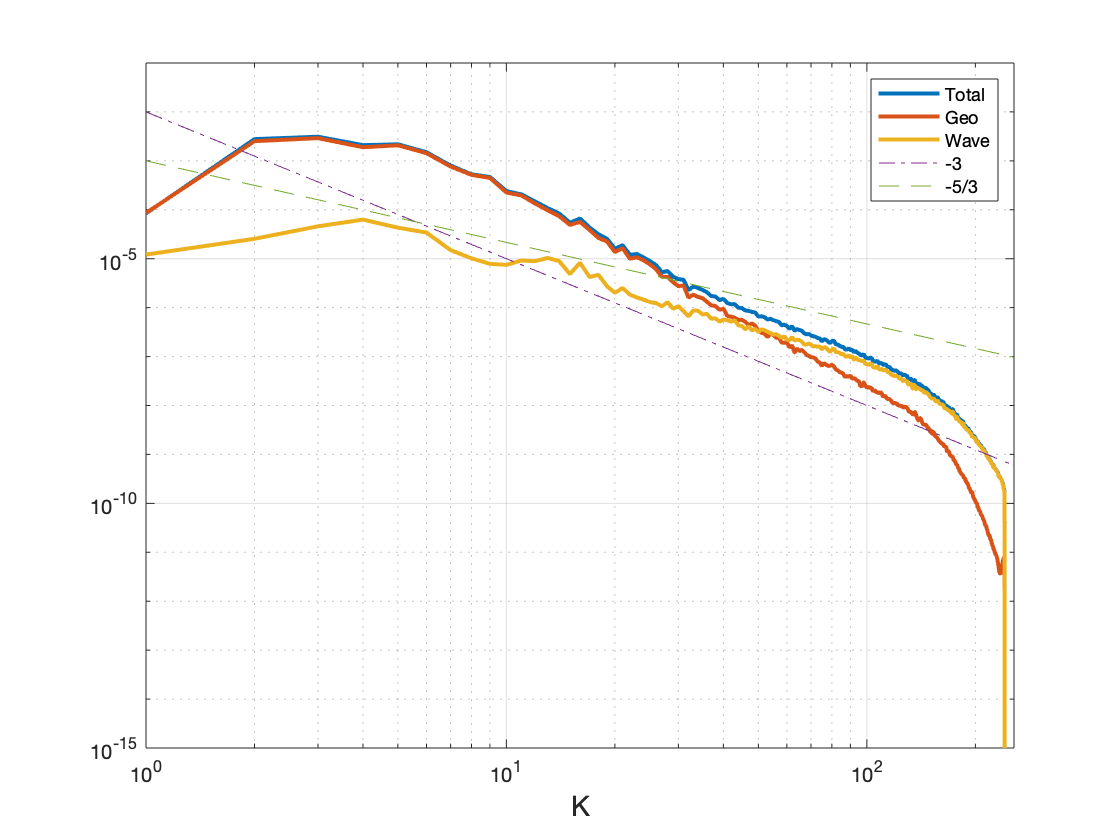

loglog(kesg,'linewidth',2)
loglog(kesw,'linewidth',2)
grid
xlabel('K','fontsize',14)

K = [1:255];
%loglog(K, K.^-4,'-')
loglog(K, 0.01*K.^-3,'-.')
loglog(K, 1e-3*K.^-(5/3),'--')
%loglog(K, 1e-3*K.^-2,'--')

axis([1 256 1e-15 0.1]) 
legend('Total','Geo','Wave','-3','-5/3')

figure
loglog(2*pi./K,kes,'linewidth',2)
hold

Current plot held


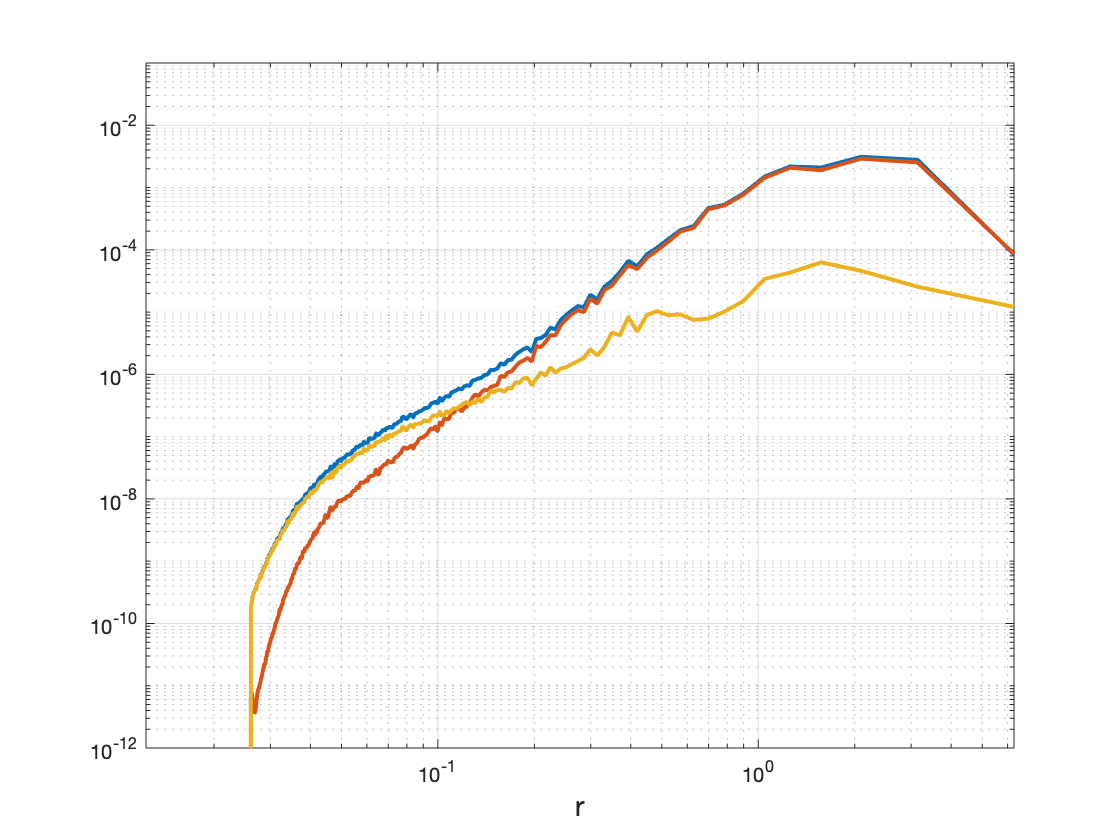

loglog(2*pi./K,kesg,'linewidth',2)
loglog(2*pi./K,kesw,'linewidth',2)
grid
xlabel('r','fontsize',14)

axis([2*pi/512 2*pi 1e-12 0.1]) 

n=15;
mask = [0*K(K<n), 1+0*K(K>=n)];

## Convert to S2

r = [2*pi./K, 0.01]; 

for i =1:length(r)
    S2_tot(i) = 2*trapz(kes.*(1-besselj(0,r(i)*K))');
    S2_geo(i) = 2*trapz(kesg.*(1-besselj(0,r(i)*K))');
    S2_wav(i) = 2*trapz(kesw.*(1-besselj(0,r(i)*K))');
    S2_wav_temp(i) = 2*trapz(mask.*kesw'.*(1-besselj(0,r(i)*K)));
end

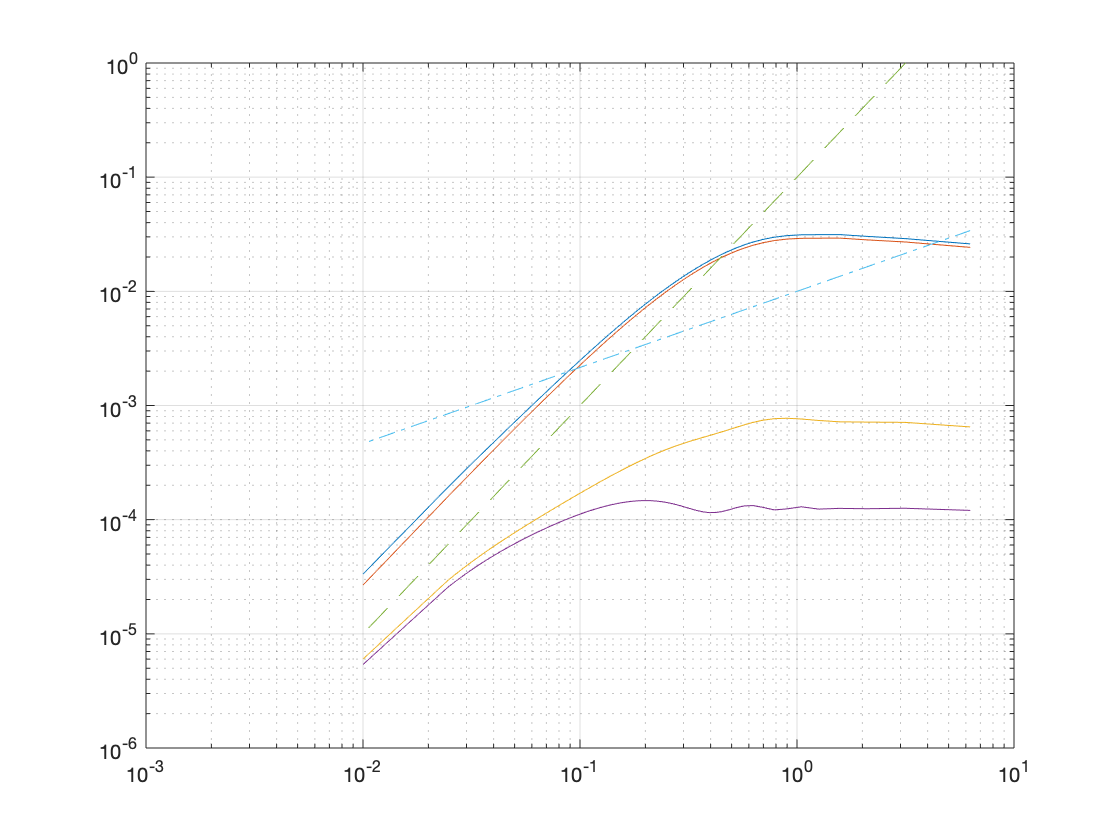

figure,
loglog(r, S2_tot)
hold all
loglog(r, S2_geo)
loglog(r, S2_wav)
loglog(r, S2_wav_temp)
loglog(r, 0.1*r.^2,'--')
loglog(r, 0.01*r.^(2/3),'-.')

axis([1e-3 10 1e-6 1])
grid

%% first define the distance axis 
gamma = 1.2;
dist_bin(1) = 2*pi/512; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>2*pi,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));


distance = [0.016, 0.02];
sep_orig = idealmodel_sep_cals(traj_orig, distance);
sep_over_inertial_samp = idealmodel_sep_cals(traj_over_inertial_samp, distance);
sep_under_inertial_samp = idealmodel_sep_cals(traj_under_inertial_samp, distance);
sep_inertial_samp = idealmodel_sep_cals(traj_inertial_samp, distance);

S2ll_orig  = S2ll_model(sep_orig.sep, dist_bin);
S2ll_over_inertial_samp  = S2ll_model(sep_over_inertial_samp.sep, dist_bin);
S2ll_under_inertial_samp  = S2ll_model(sep_under_inertial_samp.sep, dist_bin);
S2ll_inertial_samp  = S2ll_model(sep_inertial_samp.sep, dist_bin);


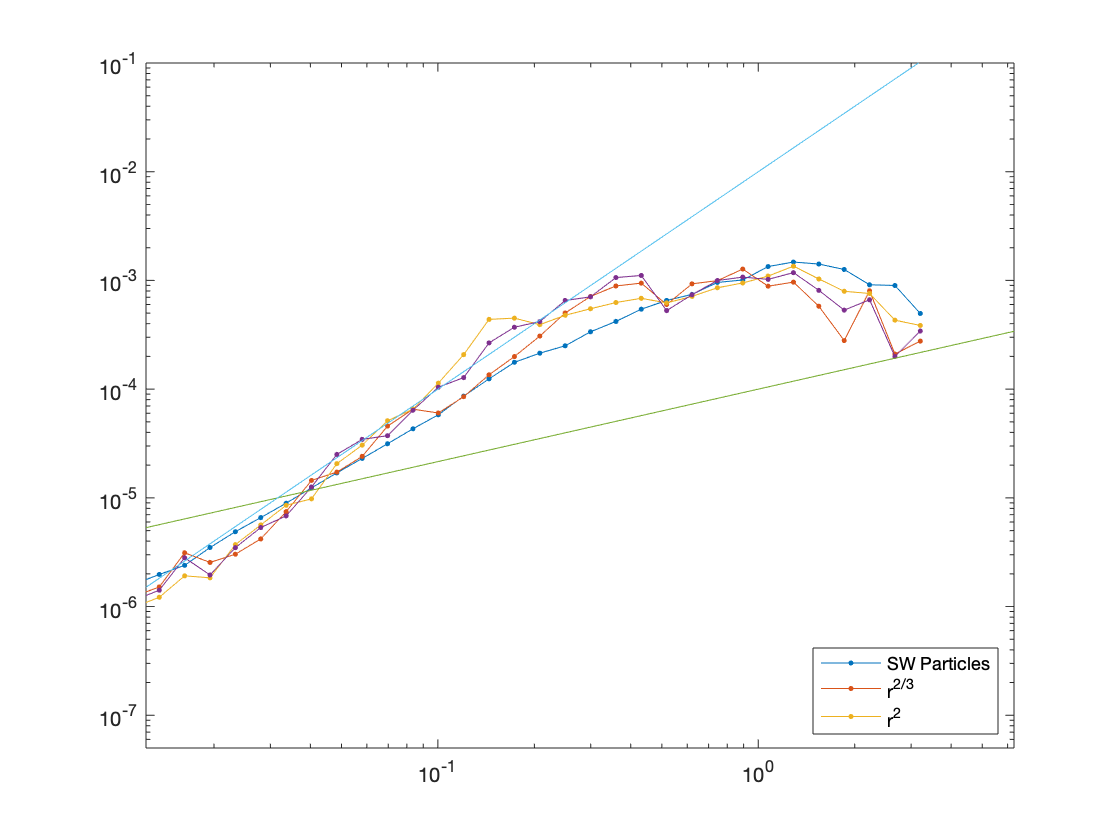

figure
loglog(dist_axis, S2ll_orig,'.-')
hold all 
loglog(dist_axis, S2ll_over_inertial_samp,'.-')
loglog(dist_axis, S2ll_under_inertial_samp,'.-')
loglog(dist_axis, S2ll_inertial_samp,'.-')
loglog(dist_axis, 1e-4*dist_axis.^(2/3))
loglog(dist_axis, 1e-2*dist_axis.^(2))
axis([2*pi/512, 2*pi, 5e-8, 1e-1])

legend('SW Particles', 'r^{2/3}', 'r^2','location','best')

fsle_orig  = fsle_model(sep_orig.sep, dist_bin,1,1);
fsle_over_inertial_samp  = fsle_model(sep_over_inertial_samp.sep, dist_bin,1,1);
fsle_under_inertial_samp  = fsle_model(sep_under_inertial_samp.sep, dist_bin,1,1);
fsle_inertial_samp  = fsle_model(sep_inertial_samp.sep, dist_bin,1,1);

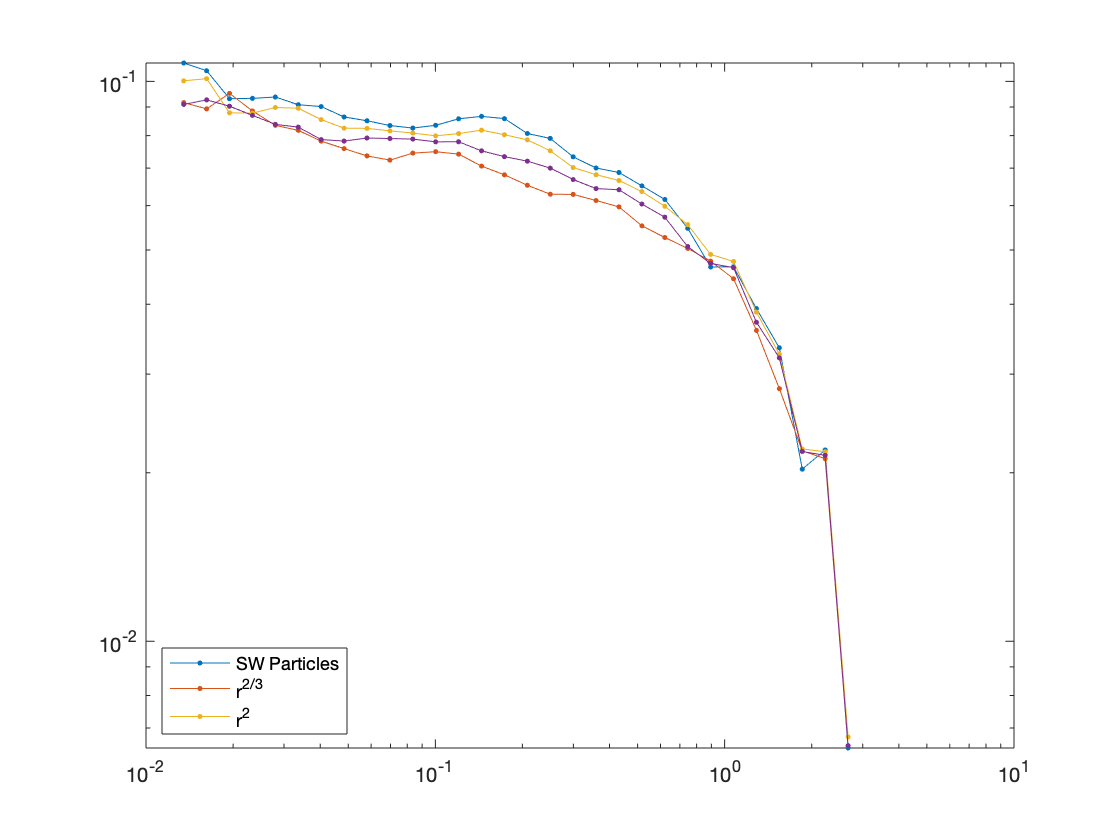

figure
loglog(dist_axis, fsle_orig,'.-')
hold all 
loglog(dist_axis, fsle_over_inertial_samp,'.-')
loglog(dist_axis, fsle_under_inertial_samp,'.-')
loglog(dist_axis, fsle_inertial_samp,'.-')
%loglog(dist_axis, 1e-4*dist_axis.^(2/3))
%loglog(dist_axis, 1e-2*dist_axis.^(2))
%axis([2*pi/512, 2*pi, 5e-8, 1e-1])

legend('SW Particles', 'r^{2/3}', 'r^2','location','best')

colors = get(gca,'Colororder');



% check dispersion 
ndays=100; 
Mod_disp = rel_disp(sep_mod.sep, ndays);
Mod_noise1_disp = rel_disp(sep_mod_noise1.sep, ndays);
Mod_noise2_disp = rel_disp(sep_mod_noise2.sep, ndays);
Mod_noise3_disp = rel_disp(sep_mod_noise3.sep, ndays);

Moddisp = Mod_disp.avdisp/1e6; 
Modnoise1disp = Mod_noise1_disp.avdisp/1e6; 
Modnoise2disp = Mod_noise2_disp.avdisp/1e6; 
Modnoise3disp = Mod_noise3_disp.avdisp/1e6; 

T = 0:99;

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
j=1;

g(i) = loglog(T+0.001, Moddisp, '--', 'color', colors(1,:), 'linewidth', 1.5);
hold all 
g(i) = loglog(T+0.001, Modnoise1disp, '-', 'color', colors(2,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise2disp, '-', 'color', colors(3,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise3disp, '-', 'color', colors(4,:), 'linewidth', 1.5);    

Tax= T(5:50);
%t3 = loglog(Tax, 10^0.7*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
%t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


%A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([1 100 10^2 3*10^4])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)$ (km$^2$)', 'Interpreter','Latex')
print('noise_disp.eps', '-depsc', '-r400')

% check relative diffusivity

mod_sep_for_sep = model_sep_calcs(mod_traj, [0, 50]*1e3); 
mod_noise1_sep_for_sep = model_sep_calcs(mod_traj_noise(1), [0, 50]*1e3); 
mod_noise2_sep_for_sep = model_sep_calcs(mod_traj_noise(2), [0, 50]*1e3); 
mod_noise3_sep_for_sep = model_sep_calcs(mod_traj_noise(3), [0, 50]*1e3); 

rd1_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,1); 

rd6_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,6); 

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd6_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd6_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd6_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd6_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff6.eps', '-depsc', '-r400')

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd1_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd1_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd1_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd1_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


%A = legend([r2, r43], ...
%    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
%    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff.eps', '-depsc', '-r400')

% Check FSLE
flag_1time= 1;
fsle_mod = fsle_model(sep_mod.sep, dist_bin, 1, flag_1time); 

figure,
loglog(dist_axis, fsle_mod)
hold all
loglog(dist_axis, 1e-4*dist_axis.^(-2/3))
loglog(dist_axis, 2e-3*dist_axis.^(0))
axis([2e-3, 2, 1e-4, 1e-2])

%% Figure for deep
close all 
clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')

        
%g(1) = loglog(dist_axis/1e3, fsle_mod_deep, '--', 'linewidth',2,'color', colors(2,:));
g(1) = loglog(dist_axis/1e3, fsle_mod, '--', 'linewidth',1.5, 'color', colors(1,:)); 
hold all 
g(2) = loglog(dist_axis/1e3, fsle_mod_noise1, '-', 'linewidth',1.5, 'color', colors(2,:)); 
g(3) = loglog(dist_axis/1e3, fsle_mod_noise2, '-', 'linewidth',1.5, 'color', colors(3,:)); 
g(4) = loglog(dist_axis/1e3, fsle_mod_noise3, '-', 'linewidth',1.5, 'color', colors(4,:)); 

r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 


A = legend([ r0, r23, r2], ...
    {'$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',18);
%legend boxoff
%set(A, 'location','best') 
set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 50*1e-4 2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')
print('noise_FSLE.eps', '-depsc', '-r400')


function [CV_mod] = complex_vels(traj)
len = length(traj.T)-1;
ntrajs = size(traj.X,2);
for nseg=1:ntrajs
    u = diff(traj.X(:,nseg))./diff(traj.T)';
    v = diff(traj.Y(:,nseg))./diff(traj.T)';
    CV_mod(:,nseg) = u + sqrt(-1)*v;
end
end

% spectra
function [traj] = spectra(traj)
len = length(traj.T)-1; 
ntrajs = size(traj.X,2);
psi = sleptap(len); 

dt= mean(diff(traj.T));

[traj.F, traj.SPP, traj.SNN, traj.SPN] = mspec(dt, traj.CV, psi,'cyclic');
end

